clear all
% rng('default') % For reproducibility


X = randi(10,40,2)

X =      4     2
     9    10
     6     1
     6     8
    10     9
     3     9
     8     1
     8     4
     4     3
     6     9



D = pdist(X,"euclidean");
ZZ = squareform(D)

ZZ =          0    9.4340    2.2361    6.3246    9.2195    7.0711    4.1231    4.4721    1.0000    7.2801    4.2426    8.5440    2.0000    4.1231    6.0000    2.0000    7.2801    4.1231    5.0000         0    7.2801    6.4031    2.0000    4.4721    3.6056    3.1623    1.4142    3.0000    3.0000    4.1231    3.1623    3.1623    8.0623   10.0000    3.6056    5.8310    2.8284   10.0000    3.6056    1.0000
    9.4340         0    9.4868    3.6056    1.4142    6.0828    9.0554    6.0828    8.6023    3.1623    9.4340    8.0000    8.5440    7.0711    8.0623   10.6301    3.1623    5.6569    8.9443    9.4340    7.0711    3.1623    7.8102    5.0000    8.6023    9.2195    9.2195    8.2462    8.2462    7.0711    6.4031   12.0416    6.0000    1.0000    8.6023    5.0000    6.7082    1.0000   10.0000    8.9443
    2.2361    9.4868         0    7.0000    8.9443    8.5440    2.0000    3.6056    2.8284    8.0000    6.4031   10.2956    1.0000    2.8284    4.1231    4.1231    8.0000    5.0990    7.0711   


Z = 1-ZZ/max(ZZ,[],"all")

Z =     1.0000    0.2588    0.8243    0.5031    0.2756    0.4444    0.6761    0.6486    0.9214    0.4280    0.6667    0.3287    0.8429    0.6761    0.5286    0.8429    0.4280    0.6761    0.6072    1.0000    0.4280    0.4969    0.8429    0.6486    0.7167    0.7515    0.8889    0.7643    0.7643    0.6761    0.7515    0.7515    0.3666    0.2143    0.7167    0.5419    0.7778    0.2143    0.7167    0.9214
    0.2588    1.0000    0.2546    0.7167    0.8889    0.5221    0.2885    0.5221    0.3241    0.7515    0.2588    0.3715    0.3287    0.4444    0.3666    0.1648    0.7515    0.5556    0.2973    0.2588    0.4444    0.7515    0.3864    0.6072    0.3241    0.2756    0.2756    0.3521    0.3521    0.4444    0.4969    0.0539    0.5286    0.9214    0.3241    0.6072    0.4730    0.9214    0.2143    0.2973
    0.8243    0.2546    1.0000    0.4500    0.2973    0.3287    0.8429    0.7167    0.7778    0.3715    0.4969    0.1911    0.9214    0.7778    0.6761    0.6761    0.3715    0.5994    0.4444    

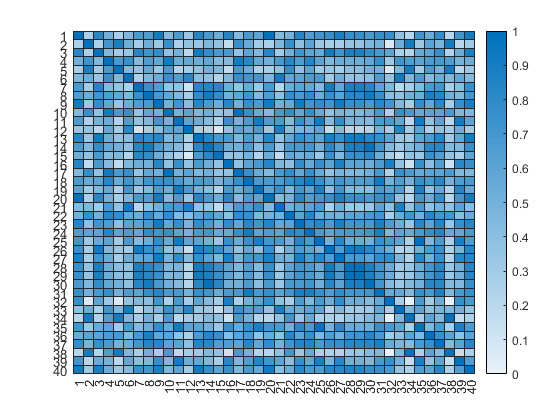

ans =   HeatmapChart with properties:

        XData: {40×1 cell}
        YData: {40×1 cell}
    ColorData: [40×40 double]

  Show all properties



heatmap(Z)

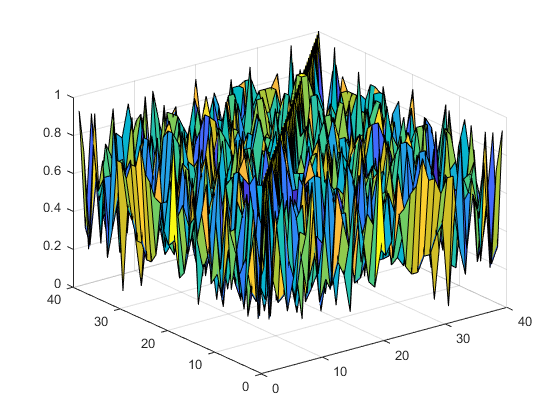

surf(Z)


sz= size(Z,1)

sz = 40

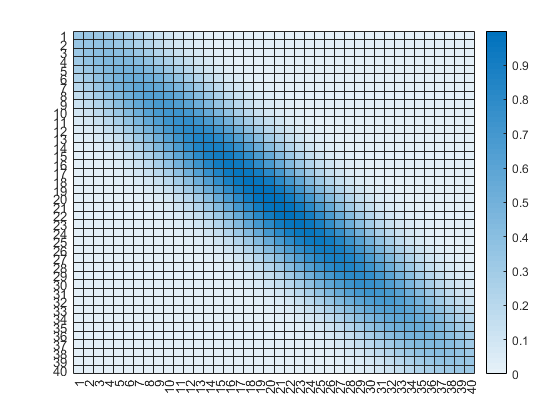

ans =   HeatmapChart with properties:

        XData: {40×1 cell}
        YData: {40×1 cell}
    ColorData: [40×40 double]

  Show all properties



rast = 1:sz;
[Xx,Yy] = meshgrid(rast,rast);
points = [Xx(:)';Yy(:)']; 
diffs = points(1,:)-points(2,:);

sigma1 = -8*log(0.01)/sz^2;
sigma2 = -log(0.3)/sz^2;
z1 = exp(-sigma1*(diffs).^2);
z2 = exp(-sigma2*(diffs).^2);

weights1 = reshape(z1, [sz sz]);
weights2 = rot90(reshape(z2, [sz sz]));

weightz = weights1.*weights2;
weightz(weightz<0.01)=0;
% weightz = diag(ones(sz-1,1),1) + diag(ones(sz-1,1),-1)

heatmap(weightz)

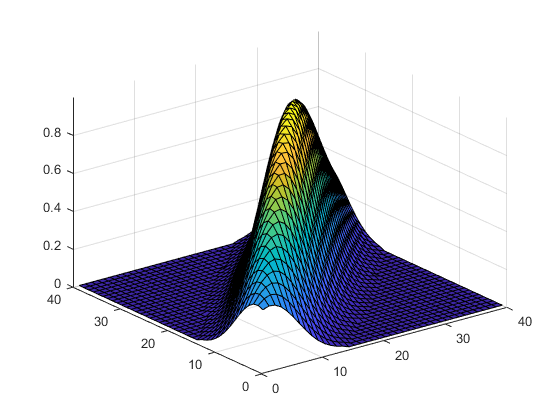

surf(weightz)
axis([0 sz 0 sz 0 inf])



weightzz = weightz(:)

weightzz =     0.3184
    0.3297
    0.3255
    0.3065
    0.2752
    0.2356
    0.1924
    0.1497
    0.1112
    0.0787



MaxGen = 10*sz;
PopSize = 8*(sz+mod(sz,2));
Mutrate= 0.2;
finalrate=0.01;
exponent = (finalrate/Mutrate)^(1/MaxGen);


% ------------------------initial population------------------------------

[optima,MORDOR] = findorder(ZZ);



for i=1:sz
    chromosome{2*i-1}=MORDOR(i,:);
    chromosome{2*i}=MORDOR(i,:);
end


for i=2*sz+1:PopSize
chromosome{i}=randperm(sz);
end

generation=[];
plot1=[];
plot2=[];
generation{1}.dna =chromosome;
generation{1}.fitness =[];



% ------------------------MAIN LOOP------------------------------
for igen= 1:MaxGen
    
    Mutrate = Mutrate*exponent;
    
    if mod(igen,10)==0
        disp(['Generation: ', num2str(igen)]);
        disp(['Mean fitness: ', num2str(mean(fitness))]);
    end
    
% ------------------------evaluate fitness scores------------------------------
%     tic
    
    
    for j=1:PopSize
        chrom = (generation{igen}.dna{j});
        
        emcee = Z(:,chrom);
        emcee = emcee(chrom,:);
                
        fitness(j) = emcee(:)'*(weightzz);
    end

    [sortedfitness,I] = sort(fitness);
    generation{igen}.fitness= fliplr(sortedfitness);
    generation{igen}.dna = generation{igen}.dna(fliplr(I));

    plot1(igen) = mean(fitness);
    plot2(igen) = sortedfitness(end);    
    
%     toc
    
 % ------------------------selecting for breeding------------------------------
%     tic
    roulette = cumsum(generation{igen}.fitness-generation{igen}.fitness(end))/sum(fitness-generation{igen}.fitness(end));
    roulette(PopSize)=1;
 
%     roulette=roulette.^0.5;
    
    for k=1:PopSize-2
    index(k) = find(roulette>rand(),1);
    end
    
    pairs= reshape(index, [], 2);
    
%     toc
    
  % ------------------------ breeding------------------------------
%     tic
    for i=1:size(pairs,1)   
   
        [xx xy]= generation{igen}.dna{pairs(i,:)};

     crossover = randi(sz);
%     crossover = 5;
    orig = crossover;
    
    offpring1 = xx;
    offpring2 = xy;
    k=0;
        while(true)
        
        offpring1(crossover) = xy(crossover);
        offpring2(crossover) = xx(crossover);
        crossover = find(xx==xy(crossover));
        
                if crossover == orig
                    break;
                end
         k=k+1;       
        end
        
        test0r(igen,i) = k;
%     offpring1
%     offpring2
%     xy    
%         
    generation{igen+1}.dna{2*i-1}=offpring1;   
    generation{igen+1}.dna{2*i}=offpring2;
    

    end
%     toc
    
 % ------------------------mutation------------------------------
%     tic
    mutindex = find(rand(1, PopSize-2)<Mutrate);
   
    for p=mutindex
            
           change  = randperm(sz,2);
           mutchrom = generation{igen+1}.dna{p};
           mutchrom(change)= mutchrom(fliplr(change));
           generation{igen+1}.dna{p} =mutchrom;
        
    end
%     toc
    
% ------------------------elitism------------------------------
    generation{igen+1}.dna{end+1}=generation{igen}.dna{1};   
    generation{igen+1}.dna{end+1}=generation{igen}.dna{2};
    
end

Generation: 10


Mean fitness: 229.1357


Generation: 20


Mean fitness: 240.3363


Generation: 30


Mean fitness: 240.9567


Generation: 40


Mean fitness: 243.0371


Generation: 50


Mean fitness: 244.7905


Generation: 60


Mean fitness: 246.34


Generation: 70


Mean fitness: 246.5625


Generation: 80


Mean fitness: 247.6047


Generation: 90


Mean fitness: 247.9563


Generation: 100


Mean fitness: 248.0639


Generation: 110


Mean fitness: 248.2862


Generation: 120


Mean fitness: 248.834


Generation: 130


Mean fitness: 249.0298


Generation: 140


Mean fitness: 249.1789


Generation: 150


Mean fitness: 249.403


Generation: 160


Mean fitness: 249.5641


Generation: 170


Mean fitness: 249.536


Generation: 180


Mean fitness: 249.5666


Generation: 190


Mean fitness: 249.9184


Generation: 200


Mean fitness: 249.9795


Generation: 210


Mean fitness: 250.077


Generation: 220


Mean fitness: 250.2688


Generation: 230


Mean fitness: 250.5929


Generation: 240


Mean fitness: 250.6124


Generation: 250


Mean fitness: 250.6695


Generation: 260


Mean fitness: 250.5085


Generation: 270


Mean fitness: 250.8447


Generation: 280


Mean fitness: 250.8331


Generation: 290


Mean fitness: 250.8601


Generation: 300


Mean fitness: 250.9081


Generation: 310


Mean fitness: 250.9492


Generation: 320


Mean fitness: 250.9144


Generation: 330


Mean fitness: 251.0672


Generation: 340


Mean fitness: 251.0664


Generation: 350


Mean fitness: 251.054


Generation: 360


Mean fitness: 251.099


Generation: 370


Mean fitness: 251.1734


Generation: 380


Mean fitness: 251.1174


Generation: 390


Mean fitness: 251.1774


Generation: 400


Mean fitness: 251.2196


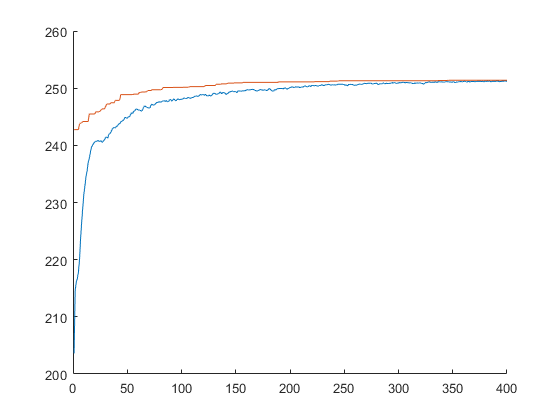


figure;
hold on
plot(plot1)
plot(plot2)
hold off

optim = generation{end}.dna{1}

optim =      6    12    21    19    39    11    25    35    32    16    27     9     1    20    40    13     3    26    28    29     7    14    30    15     8    37    23    36    24    31    18    22    17     4    10     2     5    38    34    33


% optim = generation{igen}.dna{10}
% optim = generation{igen}.dna{end-1}
% optim = generation{igen}.dna{end}
optimtest = ZZ(:,optim);
optimtest = optimtest(optim,:)%+ eye(sz);

optimtest =          0    2.2361    1.0000    3.6056    5.3852    4.4721    4.1231    4.1231    8.2462    7.0711    6.0000    6.0828    7.0711    7.0711    7.2801    7.6158    8.5440    8.9443    8.0623    8.0623    9.4340    7.8102    7.8102    9.8995    7.0711    5.8310    5.0990    7.2111    4.2426    4.4721    3.6056    5.3852    3.0000    3.1623    3.0000    6.0828    7.0000    7.0711    7.0711    1.0000
    2.2361         0    1.4142    4.0000    6.0000    5.0000    5.0990    5.0990    9.0000    8.0623    7.2801    7.6158    8.5440    8.5440    8.9443    9.4340   10.2956   10.8167   10.0000   10.0000   11.4018    9.8995    9.8995   12.0416    9.2195    7.8102    6.7082    9.4340    6.4031    6.4031    5.6569    7.6158    5.0990    5.3852    5.0990    8.0000    9.0554    9.0000    9.0000    2.0000
    1.0000    1.4142         0    3.1623    5.0990    4.1231    4.0000    4.0000    8.0623    7.0000    6.0828    6.3246    7.2801    7.2801    7.6158    8.0623    8.9443    9.4340    8.

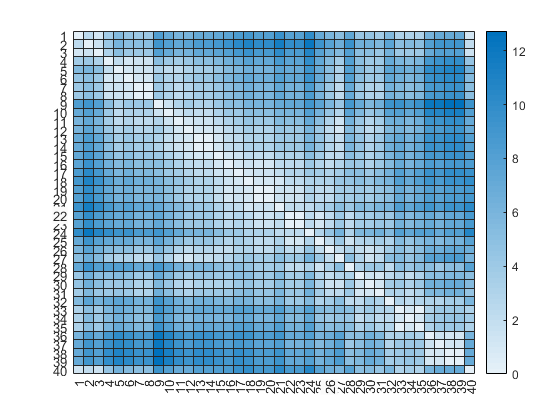


heatmap(optimtest);

sum(diag(optimtest,1))      

ans = 68.4855

optimtest(:)'*weightzz(:)

ans = 820.0001

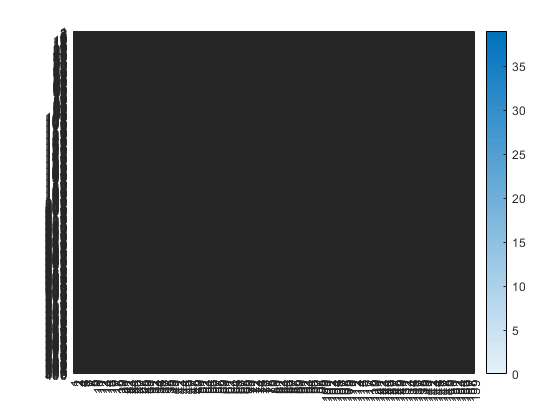

% surf(optimtest);
 heatmap(test0r);

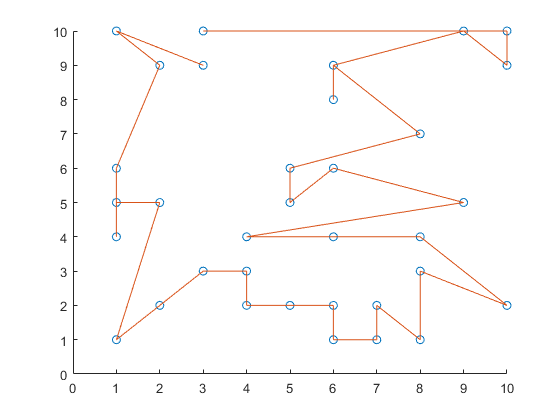

 figure;
hold on
scatter(X(:,1), X(:,2))
axis([0 10 0 10])
plottim = X(optim',:);
plot(plottim(:,1), plottim(:,2))
hold off


[optima] = findorder(ZZ);

optimtest = ZZ(:,optima);
optimtest = optimtest(optima,:) %+ eye(sz);

optimtest =          0    1.0000    1.0000    1.4142    3.1623    3.6056    3.1623    3.1623    6.0828    7.0711    8.0000    6.0000    5.6569    5.0000    6.4031    7.8102    8.6023    9.4340    9.4340    8.9443    8.5440    9.4868    9.2195    9.0554    8.2462    8.2462    7.0711    7.0711    6.0828    5.0000    8.0623    6.7082    9.2195   10.6301   12.0416   10.0000    9.4340    8.9443    8.6023    8.6023
    1.0000         0         0    1.0000    3.6056    4.4721    4.1231    4.1231    7.0711    8.0623    9.0000    7.0000    6.4031    5.6569    7.0711    8.4853    9.2195   10.0000   10.0000    9.4340    8.9443    9.8489    9.4868    9.2195    8.5440    8.5440    7.2801    7.2801    6.3246    5.0990    8.0000    7.2111    9.8995   11.3137   12.7279   10.8167   10.2956    9.8489    9.4340    9.4340
    1.0000         0         0    1.0000    3.6056    4.4721    4.1231    4.1231    7.0711    8.0623    9.0000    7.0000    6.4031    5.6569    7.0711    8.4853    9.2195   10.0000   10.

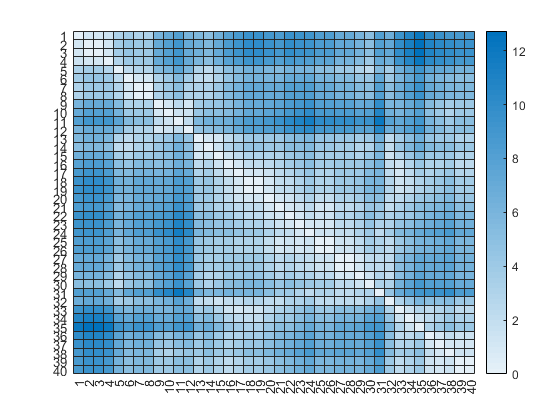

heatmap(optimtest);

sum(diag(optimtest,1)) 

ans = 56.0612

optimtest(:)'*weightzz(:)

ans = 935.8237

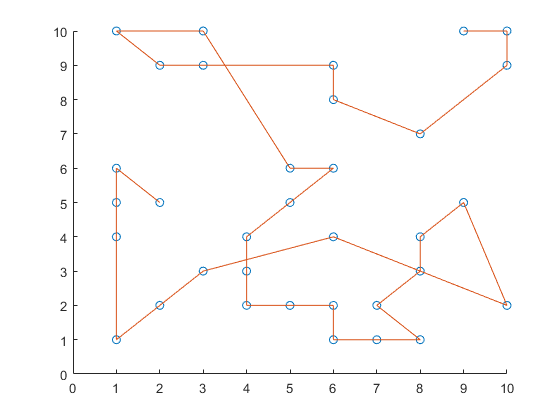


 figure;
hold on
scatter(X(:,1), X(:,2))
axis([0 10 0 10])
plottim = X(optima',:);
plot(plottim(:,1), plottim(:,2))
hold off